# SeqNMFE sandbox: Jisu Sleep Seq Analyses

close all
restoredefaultpath
global PARAMS  % these are global parameters that can be called into any function.  I limit these to directories for storing, loading, and saving files and codebases.
os = computer;

if ismac
    PARAMS.data_dir = '/Users/jericcarmichael/Documents/Williams_Lab/2019-12-04_11-10-01_537day0base1'; % where to find the raw data
    PARAMS.inter_dir = '/Users/jericcarmichael/Documents/Williams_Lab/Temp/'; % where to put intermediate files
    PARAMS.stats_dir = '/Users/jericcarmichael/Documents/Williams_Lab/Stats/'; % where to put the statistical output .txt
    PARAMS.code_base_dir = '/Users/jericcarmichael/Documents/GitHub/vandermeerlab/code-matlab/shared'; % where the codebase repo can be found
    PARAMS.code_CEH2_dir = '/Users/jericcarmichael/Documents/GitHub/CEH2'; % where the multisite repo can be found
    
elseif strcmp(os, 'GLNXA64')
    
    %     PARAMS.data_dir = '/home/ecarmichael/Documents/Williams_Lab/2019-12-04_11-10-01_537day0base1'; % where to find the raw data
    PARAMS.data_dir = '/home/ecarmichael/Documents/Williams_Lab/Raw_data/JC/7_12_2019_PV1069_LTD5'; % where to find the raw data
    %     PARAMS.raw_data_dir = '/home/ecarmichael/Documents/Williams_Lab/Raw_data/EV/';
    PARAMS.raw_data_dir = '/home/ecarmichael/Documents/Williams_Lab/Raw_data/JC/'; % raw data location.
    PARAMS.inter_dir = '/home/ecarmichael/Documents/Williams_Lab/Temp/'; % where to put intermediate files
    PARAMS.stats_dir = '/home/ecarmichael/Documents/Williams_Lab/Stats/'; % where to put the statistical output .txt
    PARAMS.code_base_dir = '/home/ecarmichael/Documents/GitHub/vandermeerlab/code-matlab/shared'; % where the codebase repo can be found
    PARAMS.code_CEH2_dir = '/home/ecarmichael/Documents/GitHub/CEH2'; % where the multisite repo can be found
    
else
    PARAMS.data_dir = 'D:\Dropbox (Williams Lab)\Williams Lab Team Folder\Eva\Processed place'; % where to find the raw data
    PARAMS.raw_data_dir = 'D:\Dropbox (Williams Lab)\Jisoo\Upload\pv1002'; % raw data location.
    PARAMS.inter_dir = 'D:\Dropbox (Williams Lab)\Jisoo\Upload\pv1002\Inter'; % where to put intermediate files
    PARAMS.stats_dir = 'D:\Dropbox (Williams Lab)\Jisoo\Upload\pv1002\Inter\Stats'; % where to put the statistical output .txt
    PARAMS.code_base_dir = 'C:\Users\ecarm\Documents\GitHub\vandermeerlab\code-matlab\shared'; % where the codebase repo can be found
    PARAMS.code_CEH2_dir = 'C:\Users\ecarm\Documents\GitHub\CEH2'; % where the multisite repo can be found
    PARAMS.code_seqnmf_dir = 'C:\Users\ecarm\Documents\GitHub\seqNMF'; % where the multisite repo can be found
    
end

rng(11,'twister') % for reproducibility

% add the required code
addpath(genpath(PARAMS.code_base_dir));

addpath(genpath(PARAMS.code_CEH2_dir));
cd(PARAMS.raw_data_dir) % move to the data folder

clear d os

## load a nice session

this_sess = 'D:\Dropbox (Williams Lab)\Jisoo\Upload\pv1002\3_26_2019';
cd(this_sess);
load('ms.mat');
load('behav.mat');
load('AllSpatialFiringData.mat')

## plug it into SeqNMF

addpath(PARAMS.code_seqnmf_dir)
Fs =mode(diff(ms.time));

% data_in = ms.FiltTraces';
data_in = ms.Binary';

pos(:,1) = interp1(behav.time,behav.position(:,1),ms.time);
pos(:,2) = interp1(behav.time,behav.position(:,2),ms.time);
velocity = interp1(behav.time, behav.speed, ms.time); 


% remove inactive cells
% total_act = sum(data_in,2);

% keep_idx = total_act>30; % exclude cells that are active for less than 1s total

% data_in = data_in(keep_idx,:);

## sort data based on place field location.

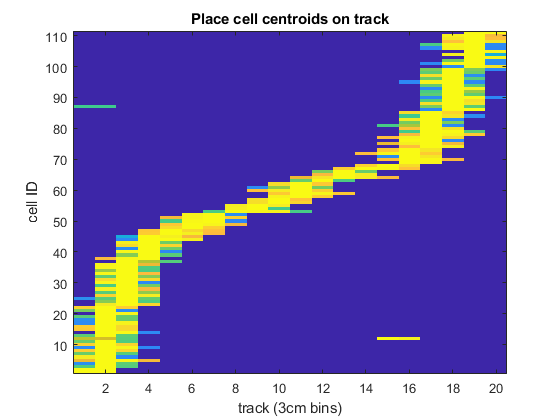

    centroids = []; 
    for iC =length(AllSpatialFiringData):-1:1
        temp = AllSpatialFiringData(iC).PlaceFieldCentroid; 
        centroids(iC) = temp(1);
        
        % is it a place cell?
        Place_Cell_D1(iC) = AllSpatialFiringData(iC).IsPlaceCell; 
        
        place_map_1d(iC,:) = mean(AllSpatialFiringData(iC).PlaceField,1)/max(mean(AllSpatialFiringData(iC).PlaceField,1)); % get the 1d place field and normalize. 
    end
        
    % limit to predefined place cells.
    data_in = data_in(Place_Cell_D1,:);
    
% sort the centroids (1D only)
    centroids = centroids(Place_Cell_D1);

[~,sort_idx] = sort(centroids);

place_map_1d = place_map_1d(Place_Cell_D1,:);
place_map_1d = place_map_1d(sort_idx,:);

imagesc(place_map_1d)
axis xy
title('Place cell centroids on track')
xlabel('track (3cm bins)')
ylabel('cell ID')

data_in = data_in(sort_idx,:); 

% %% run the normalizing steps from SeqNMFE paper: Since seqNMF would 
% % prioritize the neurons with the most power, we renormalized by dividing 
% % the signal from each neuron by the sum of the maximum value of that row 
% % and the 95th percentile of the signal across all neurons. In this way, 
% % neurons with larger peaks were given some priority, but not much more 
% % than that of neurons with weaker signals.
% 
% p_95 = prctile(data_in, 95, 'all');
% for iC = size(data_in, 1):-1:1
%    data_in(iC,:) =  (data_in(iC,:) / sum(data_in(iC,:)))/p_95;
%    data_in(iC,:) = data_in(iC,:) + abs(min(data_in(iC,:)));
%     
% end

## limit to laps

movement_thresh = 2.5; % in cm/s
movement_idx = velocity >movement_thresh; % get times when the animal was moving.

left_idx = MS_get_direction(pos(:,1), -.1); % use -threshold for leftbound and + for right.
right_idx = MS_get_direction(pos(:,1), .1); % use -threshold for leftbound and + for right.

left_idx = left_idx & movement_idx; % only keep the indices when they are moving to the left.
right_idx = right_idx & movement_idx;

[L_laps, L_lap_start_idx, L_lap_end_idx] = MS_get_laps(left_idx, floor(1.5*(Fs)),floor(10*(Fs)));
[R_laps, R_lap_start_idx, R_lap_end_idx] = MS_get_laps(right_idx, floor(1.5*(Fs)),floor(10*(Fs)));

% make L and R lap only data sets. 
L_data = data_in(:,L_laps > 0);
R_data = data_in(:,R_laps > 0);

## for plotting get the position during laps.

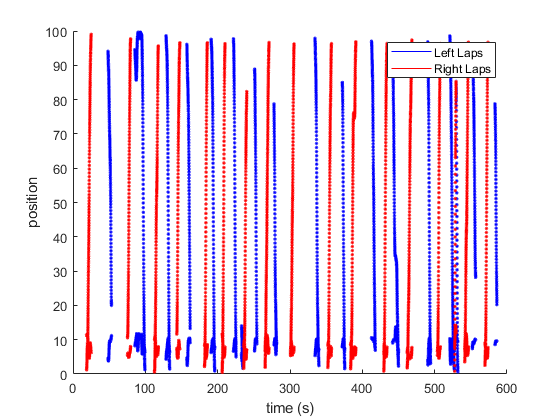

L_laps_pos = pos(L_laps > 0,:);
L_laps_time = ms.time(L_laps >0,:);

R_laps_pos = pos(R_laps > 0,:);
R_laps_time = ms.time(R_laps >0,:);

figure(111)
hold on
% plot(ms.time, pos, 'color', [.2 .2 .2])
plot(L_laps_time/1000, nan(length(L_laps_pos),1), 'b')
plot(R_laps_time/1000, nan(length(R_laps_pos),1), 'r')

plot(L_laps_time/1000, L_laps_pos, '.b')
plot(R_laps_time/1000, R_laps_pos, '.r')
xlabel('time (s)')
ylabel('position')
legend({'Left Laps', 'Right Laps'})


% split the velocity values 
L_velo = []; R_velo = []; 
for iL = 1:length(L_lap_start_idx)
    L_velo = [L_velo; velocity(L_lap_start_idx(iL):L_lap_end_idx(iL))];% append the velocity values for each R lap
end
for iL = 1:length(R_lap_start_idx)
    R_velo = [R_velo; velocity(R_lap_start_idx(iL):R_lap_end_idx(iL))]; % append the velocity values for each R lap
end

% convert trajectory to 3d mat as place x time x logical (was the animal here) for plotting
% in the SeqNMFe WHPlot function
p_range = floor(min(L_laps_pos(:,1))):0.5:ceil(max(L_laps_pos)); % make a range of positions which the middle value here being the precision (default 0.5cm)
L_pos_mat = [];
for iP = length(L_laps_pos):-1:1
    pos_idx= nearest_idx(L_laps_pos(iP), p_range);
        pos_val = zeros(size(p_range));   % hack to have zeros in all the other positions. 
    pos_val(pos_idx) = 1;
%     pos_val(pos_idx) = L_velo(iP);
    L_pos_mat(iP,:) = smooth(pos_val,10); % fill in the y axis with zeros for unoccupied and 1 for occupied. 
end

p_range = floor(min(R_laps_pos(:,1))):0.5:ceil(max(R_laps_pos)); % make a range of positions which the middle value here being the precision (default 0.5cm)
R_pos_mat = [];
for iP = length(R_laps_pos):-1:1
    pos_idx= nearest_idx(R_laps_pos(iP), p_range);
    pos_val = zeros(size(p_range));   % hack to have zeros in all the other positions. 
%     pos_val(pos_idx) = R_velo(iP);
    pos_val(pos_idx) = 1;
    R_pos_mat(iP,:) = smooth(pos_val,10); % fill in the y axis with zeros for unoccupied and 1 for occupied. 
end


## Fit with seqNMF: most of this is straight out of Mackevicius et al. 2019 [https://elifesciences.org/articles/38471](https://elifesciences.org/articles/38471)

this_data = data_in; % which data to use. this_data = R_data;

this_data = L_data;
this_pos = L_pos_mat;

PosFs = Fs; % b/c we already interpolated the position data to the ms.time. 

% break data into training set and test set
splitN = floor(size(this_data,2)*.75); 
splitS = floor(size(this_pos,2)*.75);

% make the test/trian sets.  
trainNEURAL = this_data(:,1:splitN); 
trainPOS = this_pos(:,1:splitS); 
testNEURAL = this_data(:,(splitN+1):end); 
testPOS = this_pos(:,(splitS+1):end);


%% Set some parameters
rng(235); % fixed rng seed for reproduceability
X = trainNEURAL;
figure
% loop L values
% Ls = fliplr([0.5 1 2 10 50 100 1000]);
% 
% for iS = length(Ls):-1:1
K = 2;
L = 10;
% L = Ls(iS); % units of seconds
Lneural = ceil(L*Fs);  
% Lsong = ceil(L*SONGfs);



## Procedure for choosing lambda

nLambdas = 30; % increase if you're patient
K = 3; 
X = trainNEURAL;
lambdas = sort([logspace(-2,-4.5,nLambdas)], 'ascend'); 
loadings = [];
regularization = []; 
cost = []; 
for li = 1:length(lambdas)
    [N,T] = size(X);
    [W, H, ~,loadings(li,:),power]= seqNMF(X,'K',K,'L',Lneural,...
        'lambdaL1W', .1, 'lambda', lambdas(li), 'maxiter', 100, 'showPlot', 0); 
    [cost(li),regularization(li),~] = helper.get_seqNMF_cost(X,W,H);
    display(['Testing lambda ' num2str(li) '/' num2str(length(lambdas))])
end

Testing lambda 1/30
Testing lambda 2/30
Testing lambda 3/30
Testing lambda 4/30
Testing lambda 5/30
Testing lambda 6/30
Testing lambda 7/30
Testing lambda 8/30
Testing lambda 9/30
Testing lambda 10/30
Testing lambda 11/30
Testing lambda 12/30
Testing lambda 13/30
Testing lambda 14/30
Testing lambda 15/30
Testing lambda 16/30
Testing lambda 17/30
Testing lambda 18/30
Testing lambda 19/30
Testing lambda 20/30
Testing lambda 21/30
Testing lambda 22/30
Testing lambda 23/30
Testing lambda 24/30
Testing lambda 25/30
Testing lambda 26/30
Testing lambda 27/30
Testing lambda 28/30
Testing lambda 29/30
Testing lambda 30/30


## plot Lambda cost

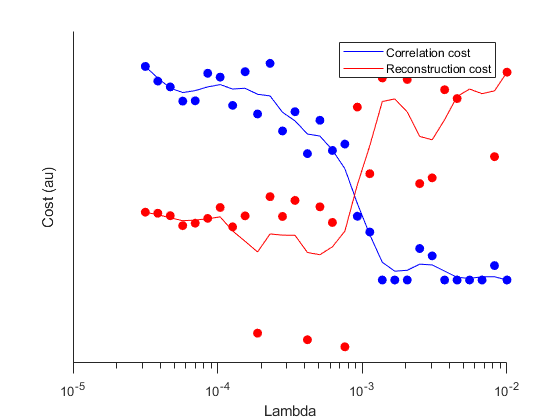

windowSize = 3; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;
Rs = filtfilt(b,a,regularization); 
minRs = prctile(regularization,10); maxRs= prctile(regularization,90);
Rs = (Rs-minRs)/(maxRs-minRs); 
R = (regularization-minRs)/(maxRs-minRs); 
Cs = filtfilt(b,a,cost); 
minCs =  prctile(cost,10); maxCs =  prctile(cost,90); 
Cs = (Cs -minCs)/(maxCs-minCs); 
C = (cost -minCs)/(maxCs-minCs); 

figure; hold on
plot(lambdas,Rs, 'b')
plot(lambdas,Cs,'r')
scatter(lambdas, R, 'b', 'markerfacecolor', 'flat');
scatter(lambdas, C, 'r', 'markerfacecolor', 'flat');
xlabel('Lambda'); ylabel('Cost (au)')
set(legend('Correlation cost', 'Reconstruction cost'), 'Box', 'on')
set(gca, 'xscale', 'log', 'ytick', [], 'color', 'none')
set(gca,'color','none','tickdir','out','ticklength', [0.025, 0.025])

shg

% extract best lambda   


## look for sequences using lambda

lambda = 0.005;% from the above.  "Go just above the cross point"
fprintf('Running seqNMF...K = %d  L = %d sec\n', K, L)

Running seqNMF...K = 3  L = 10 sec


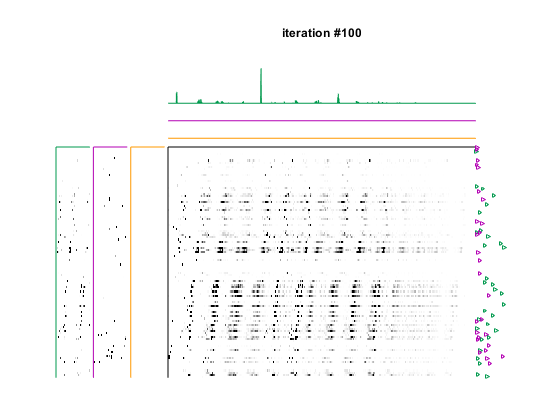

[W, H, ~,loadings,power]= seqNMF(X,'K',K,'L',Lneural,...
            'lambdaL1W', .1, 'lambda', lambda, 'maxiter', 100, 'showPlot', 1,...
            'lambdaOrthoW', 0);

p = .05; % desired p value for factors

disp('Testing significance of factors on held-out data')

Testing significance of factors on held-out data


[pvals,is_significant] = test_significance(testNEURAL,W,p);

W = W(:,is_significant,:); 
H = H(is_significant,:); 
fprintf('Found %d/%d significant factors\n', sum(is_significant), length(is_significant))

Found 0/3 significant factors


% all_sweeps{iS}.K = K;
% all_sweeps{iS}.L = L;
% all_sweeps{iS}.W = W;
% all_sweeps{iS}.H = H;
% all_sweeps{iS}.sig = is_significant;
% all_sweeps{iS}.Train = trainNEURAL;
% all_sweeps{iS}.Trest = testNEURAL;
% 
% saveas(gcf,['Seq_Sweeps' filesep 'Sweep_' num2str(L)], 'png')
% clearvars -except all_sweeps trainNEURAL testNEURAL Ls

% end

plot, sorting neurons by latency within each factor

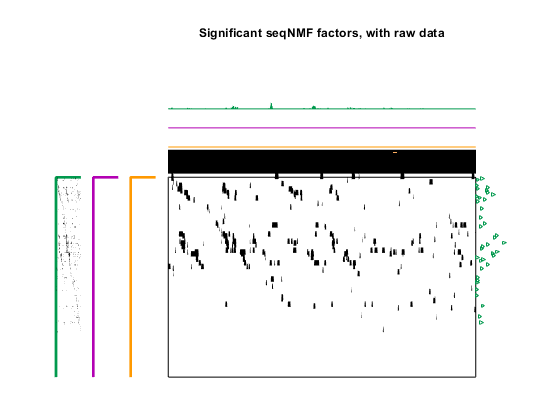

[max_factor, L_sort, max_sort, hybrid] = helper.ClusterByFactor(W(:,:,:),1);
indSort = hybrid(:,3);
tstart = 1; % plot data starting at this timebin
figure;
WHPlot(W(indSort,:,:),H(:,tstart:end), X(indSort,tstart:end), ...
    0,trainPOS(:,floor(tstart*Fs/PosFs):end))
title('Significant seqNMF factors, with raw data')

figure;
WHPlot(W(indSort,:,:),H(:,tstart:end), ...
    helper.reconstruct(W(indSort,:,:),H(:,tstart:end)),...
    0,trainPOS(:,floor(tstart*Fs/PosFs):end))

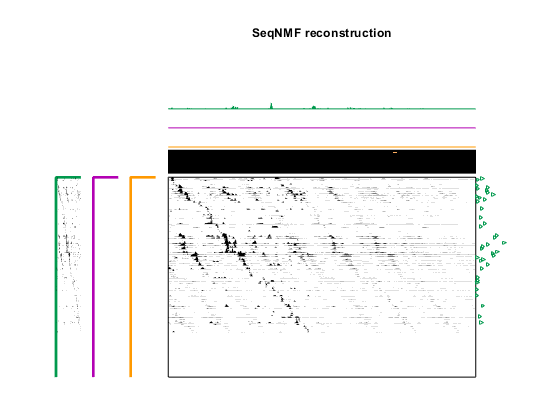

title('SeqNMF reconstruction')